load("measureData.mat");
fs = 100;
Ts = 1/fs;
time = 0:Ts:8500*fs;
J = 2.6864/10000

J = 2.6864e-04

w = 18.65

w = 18.6500

w_fs = w/fs

w_fs = 0.1865

code2w = w_fs/0.4

code2w = 0.4662

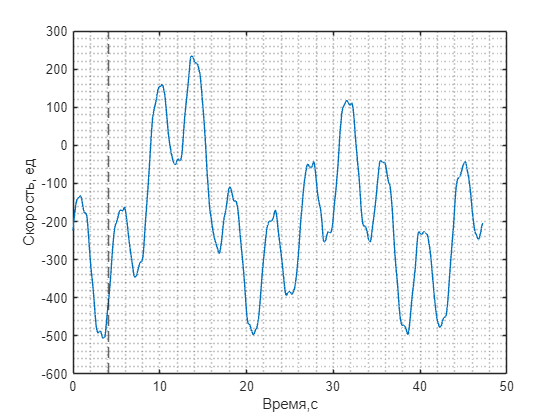

figure
plot(time(1:4725),test5nm.val2(1:4725));
grid(gca, 'minor')

xlabel("Время,с")
ylabel("Скорость, ед");
hold on
xline(4.1,'--');

figure
L = length(test5nm.val2);
Y = fft(test5nm.val2);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

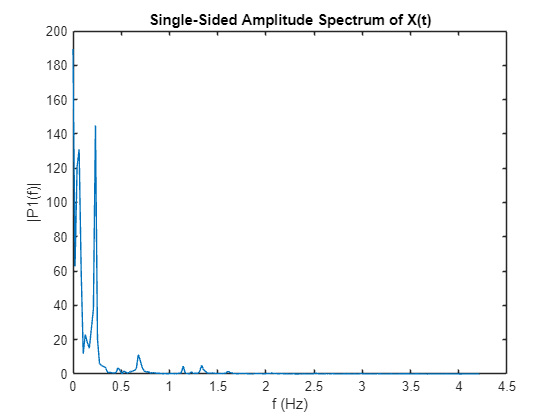

P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(L/2))/L;
plot(f(1:200),P1(1:200))
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

Ускорение угловых колебаний при воздействии тестового маховика

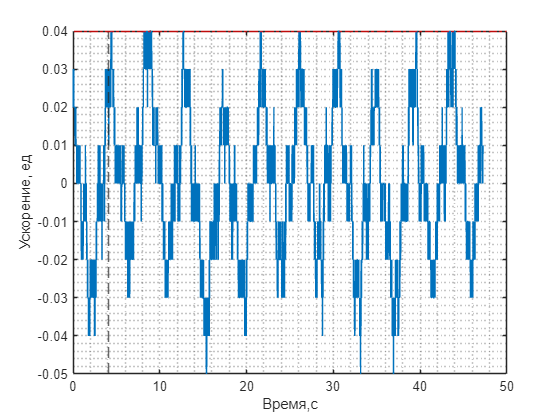

TestAcceleration = diff(test5nm.val2)*Ts;

figure
plot(time(1:4724), TestAcceleration(1:4724));
grid(gca, 'minor')
hold on
xline(4.1,'--');
yline(0.04, '-.r');
xlabel("Время,с")
ylabel("Ускорение, ед");

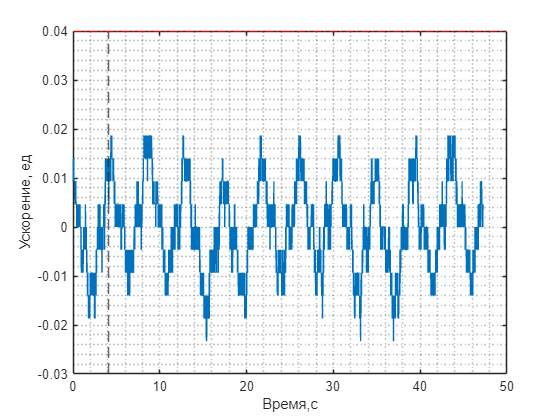

TestAccelerationW = TestAcceleration.* code2w;
figure
plot(time(1:4724), TestAccelerationW(1:4724));
grid(gca, 'minor')
hold on
xline(4.1,'--');
yline(0.04, '-.r');
xlabel("Время,с")
ylabel("Ускорение, ед");

Скорость колебаний рамы при сканировании

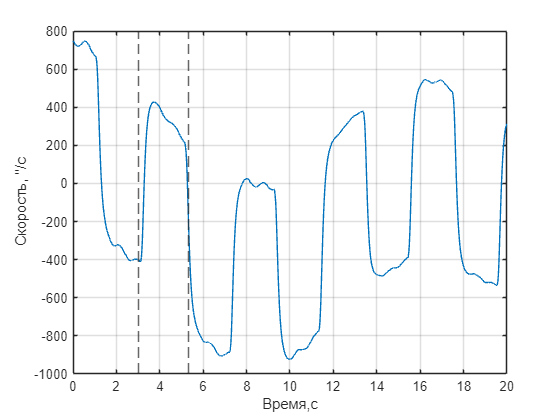

figure
plot(time(1:2000),scaner.val2(1:2000));
grid on

xlabel("Время,с")
ylabel("Скорость, ''/c");
hold on
xline(3,'--');
xline(5.3,'--')
xticks(0:2:20)

Ускорение колебаний рамы при сканировании

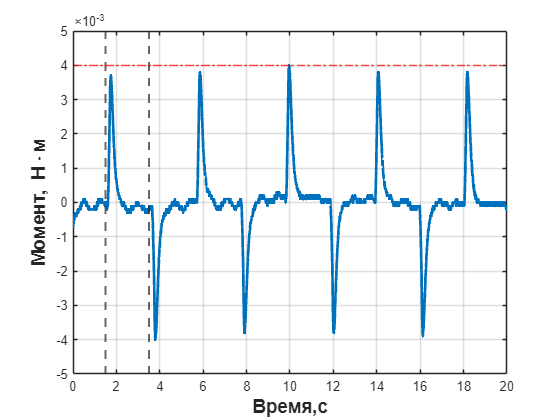

ScanerAcceleration = diff(scaner.val2) * Ts;
acc = ScanerAcceleration(150:2150)*0.01;
tt = 0:0.01:50;
fig = figure;
plot(tt(1:length(acc)), acc, "LineWidth",2);
grid on
hold on
beautifyPlot("Время,с", "Момент, Н\cdotм","")
xline(1.5,'--', 'LineWidth', 1.5);
xline(3.5,'--', 'LineWidth',1.5);
yline(max(acc), '-.r');
xticks(0:2:50)
ylim([-0.005 0.005])
print(gcf, '../img/scanner_correct.png','-dpng','-r300')   % PNG, 300 dpi

Скорость колебаний рамы при вращении маховика

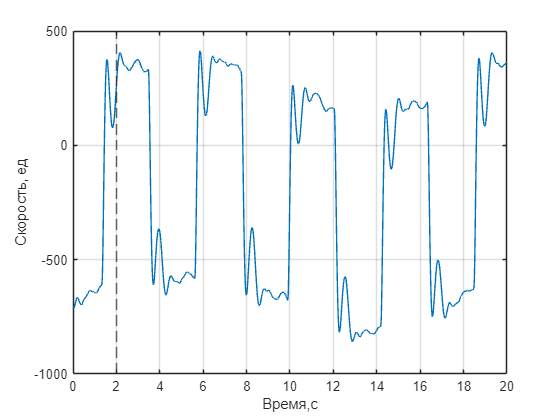

figure
plot(time(1:2000),flyWeel.val2(1:2000));
grid on

xlabel("Время,с")
ylabel("Скорость, ед");
hold on
xline(2,'--');
xticks(0:2:50)

Ускорение колебаний рамы при вращении маховика

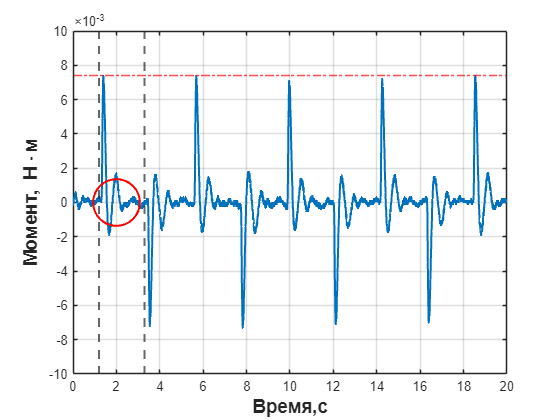

FlyWeelAcceleration = diff(flyWeel.val2) * Ts * 0.01;

figure
plot(time(1:2000), FlyWeelAcceleration(1:2000), "LineWidth",1.5);
grid on
hold on
xline(1.2,'--',"LineWidth",1.5);
xline(3.3,'--',"LineWidth",1.5);
yline(max(FlyWeelAcceleration), '-.r');
xlabel("Время,с")
ylabel("Ускорение, ед");
beautifyPlot("Время,с", "Момент, Н\cdotм","")
ax = gca;                              % получить текущие оси
ax.YRuler.ExponentMode = 'manual';     % отключить авто-режим
ax.YAxis.Exponent = -3;                % принудительно поставить ×10^-3
ylim([-0.01 0.01])
xticks(0:2:50)

% Координаты центра и радиус круга
xc = 2;   % центр по X
yc = 0.000; % центр по Y
r  = 0.001; % радиус


plot(xc, yc, 'or','MarkerSize',35,'LineWidth',1.5)

print(gcf, '../img/scanner_no_sinchron.png','-dpng','-r300')   % PNG, 300 dpi

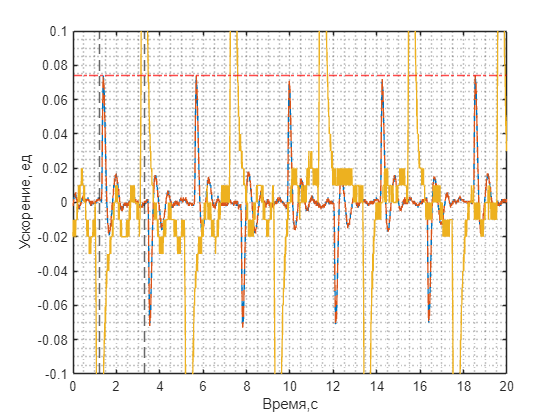

plot(time(1:2000), FlyWeelAcceleration(1:2000), "--")
hold on
plot(time(1:2000), ScanerAcceleration(1:2000))

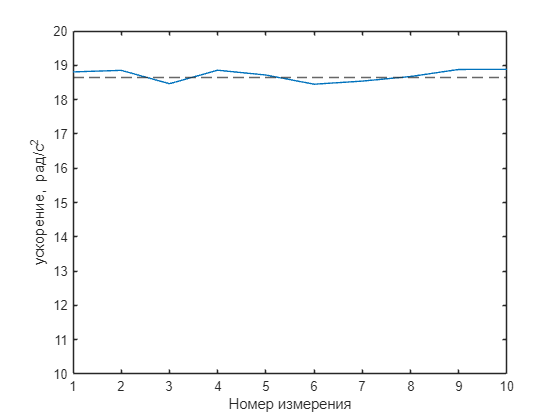


figure
sko = 0.250;
r = -sko + (sko+sko)*rand(10,1);
wmeasure = r+w_fs*fs;
plot(wmeasure);
yline(w_fs*fs,'--');
xlabel("Номер измерения")
ylabel("ускорение, рад/с^2");
xlim([1 10])
ylim([10 20])

myStd = std(wmeasure)

myStd = 0.1729

myStd = 0.1147

myStd = 0.1147

d = dms2degrees([0 1 15])

d = 0.0208

rad = deg2rad(d)

rad = 3.6361e-04

theta = 0.0003 %поргешность ДУ

theta = 3.0000e-04

t = 2.2281; %коэфф стьюдента
skoRms = myStd/sqrt(length(wmeasure))

skoRms = 0.0363

epsilon = t * skoRms

epsilon = 0.0808

skoNSP = theta/sqrt(3)

skoNSP = 1.7321e-04



summError = sqrt(skoNSP * skoNSP + skoRms *skoRms  )

summError = 0.0363



K = (epsilon + theta)/(skoNSP + skoRms)

K = 2.2257


absol = K*summError

absol = 0.0807

figure
fs = 100;
Ts = 1/fs;
w = 0.005/J

w = 18.6123

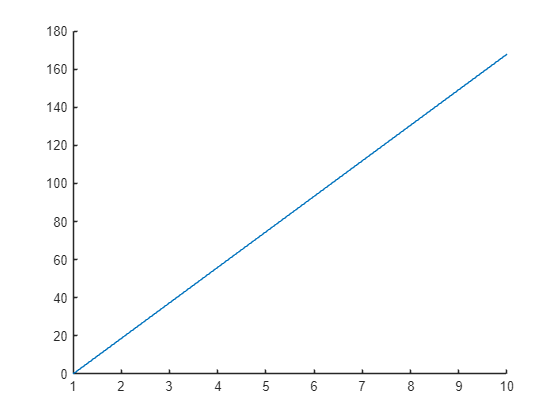


dt = 0:9;
idealfI = dt .* w_fs*fs;
idealfI = idealfI';

hold on
plot(idealfI)